## Test running COMSOL to calculate bandgap

Test each step of bandgap calculating process.

%% Clear before running
clear all

mech = StudyType.Mechanical;
opt = StudyType.Optical;

## Load the COMSOL model

import com.comsol.model.*
import com.comsol.model.util.*

if numel(mphtags) == 1
    model = mphload('Model')
else
    model = mphopen('mphFiles/Bands_SYM.mph', 'Model')
end


model =

COMSOL Model Object
Name: Bands_SYM.mph
Tag: Model
Identifier: root



## Set COMSOL model parameters

%% Parameters
h = 530e-9;     % Beam vertical (z-direction) [m]
w = 560e-9;     % Beam width (y-direction) [m]
a = 591e-9;     % Default lattice constan [nm], prefactors below.

% nominal unit cell geometry
% fill factor (ff) in units of a (unit cell lattice constant)
ffx = 0.30;     %(x radius of nominal ellipse) 
ffy = 0.30;     %(y radius of nominal ellipse) 
a_factor = 0.9; % additional prefactor for default a. 

% cavity(defect) unit cell geometry
ffx_cav = 0.30;     %(x radius of cavity ellipse) 
ffy_cav = 0.30;     %(y radius of cavity ellipse)
a_factor_cav = 0.85 * 0.9;  % additional prefactor for default a. 

%% Simulation parameters

n_mech = 6;     % number of mechanical modes to find (min. 3 for fixBandData())
dk_mech = 0.1;  % k-points spacing (from k=0 to k=1)
f_mech = 0;     % mechanical frequency to search around
sel_mech = 2;   % highlight a band as cavity mode (usually 2 for breathing mode)

n_opt = 3;              % number of optical modes/bands to find
dk_opt = 0.05;           % k-point spacing
l_opt = 0.75 * 1550e-9; % optical wavelength to search around
sel_opt = 1;            % highlight a band as cavity mode

a_nom = a_factor * a;       % nominal unit cell lattice constant
a_cav = a_factor_cav * a;   % nominal unit cell lattice constant

%% Set geom parameters for COMSOL
hx_cav = ffx_cav*a_cav*2;   % x-diam of cavity ellipse in [nm] 
hy_cav = ffy_cav*a_cav*2;   % y-diam of cavity ellipse in [nm] 
hx_nom = ffx*a_nom*2;       % x-diam of nominal ellipse in [nm] 
hy_nom = ffy*a_nom*2;       % y-diam of nominal ellipse in [nm] 

study = opt;

% Setup optical parameters
setModelParameters(...
    model, study, h=h, w=w, a=a_nom, dk=dk_opt, n=n_opt, l=l_opt, hx=hx_nom, hy=hy_nom ...
)

## Run COMSOL study

tic
runStudy(model, study);
toc

Elapsed time is 75.743310 seconds.


## Get COMSOL results

tic
fTable = getResults(model, study);

% Split study data into however many bands needed
[kx, f] = fixBandData(fTable);
toc

Elapsed time is 3.771256 seconds.


## Get bandgaps

[gaps, gapFloors] = getBandgaps(study, kx, f, a_nom);
gapCenters = gapFloors + 0.5*gaps;

for i = 1:length(gaps)
    fprintf('Center: %.5f THz Bandgap: %.5f THz\n', ...
        gapCenters(i)*1e-12, gaps(i)*1e-12 ...
    )
end

Center: 209.82425 THz Bandgap: 50.40244 THz
Center: 262.76350 THz Bandgap: 48.04627 THz


## Plot Bandgap

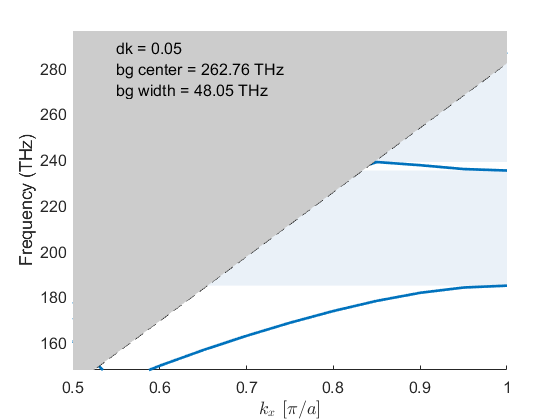

fontsize = 12;
figure('DefaultAxesFontSize', fontsize)
hold on
plotGap(kx, f, gapFloors, gaps, sel_opt, a_nom, "opt", "#0072BD", "#0072BD")
title('')
txt = {...
    append('dk = ', mat2str(dk_opt)), ...
    append('bg center = ', mat2str(gapCenters(i)*1e-12, 5), ' THz'), ...
    append('bg width = ', mat2str(gaps(i)*1e-12, 4), ' THz')
};
text(0.55, 280, txt, 'FontSize', fontsize)
hold off

saveas(gcf, append('figures/mirror-cell-band-diagram-dk', mat2str(dk_opt), '.png'))